# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The result may be infinite or negative. Neither is a good state.
ix = isinf(solvers.result)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers

solvers = 2x5 timetable
             t              result    computeTime    score      author                         commit                   
    ____________________    ______    ___________    _____    __________    ____________________________________________

    06-May-2024 21:52:36    26.017      0.34412      164.5    {'gulley'}    {'c51b2fcf7b51ebe382d55723d14c15474980b116'}
    06-May-2024 21:58:25    8447.5     0.010434      42238    {'gulley'}    {'0b53da950386771ea06a279705761aca016bc1c5'}


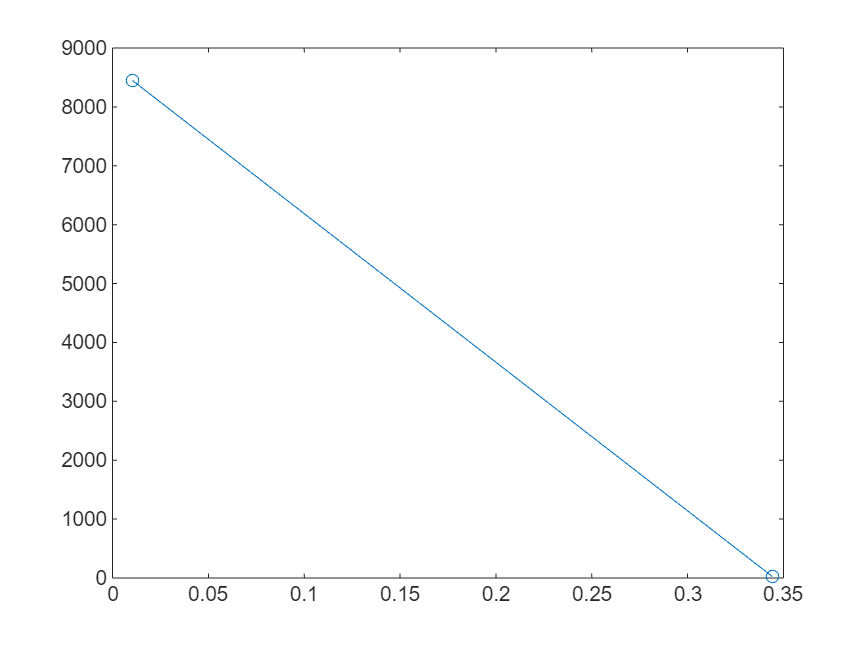

plot(solvers.computeTime,solvers.result,"-o")

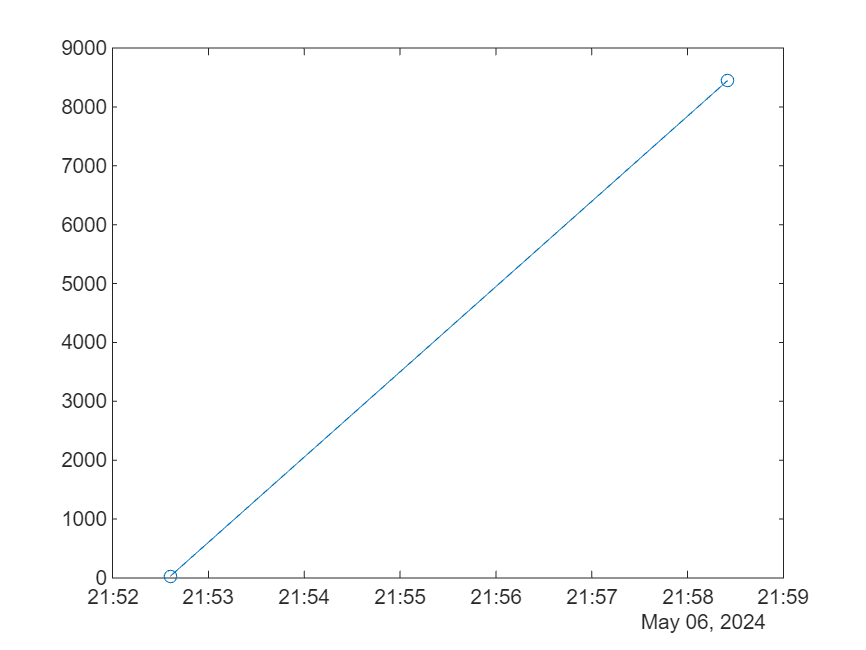

plot(solvers.t,solvers.result,"-o")

Calculate leaders

bestScore = inf;
ixLeader = zeros(height(t),1);
for i = 1:height(solvers)
    if solvers.score(i) < bestScore
        ixLeader(i) = 1;
        bestScore = solvers.score(i);
    end
end

leaders = solvers(ixLeader,:)

leaders = 1x5 timetable
             t              result    computeTime    score      author                         commit                   
    ____________________    ______    ___________    _____    __________    ____________________________________________

    06-May-2024 21:52:36    26.017      0.34412      164.5    {'gulley'}    {'c51b2fcf7b51ebe382d55723d14c15474980b116'}
